# MCSB Bootcamp - Some Matlab notes

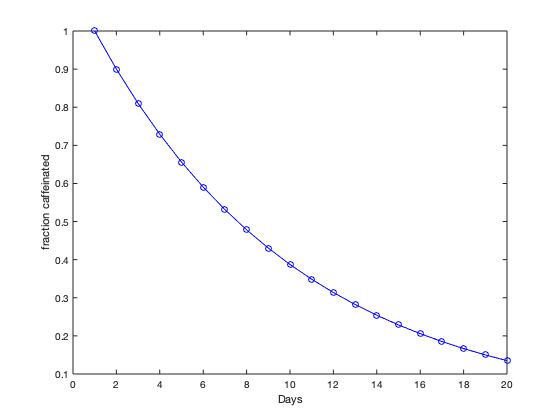

% How much caffeine is there in the jar?

% n - number of days
% x - fraction of caffeinated 

nMax = 20; % max number of days to simulate

N = 10; % number of scoops in each jar
x = zeros(1,nMax); % fraction caffeinated
x(1) = 1.0; % initial fraction caffeinated

for n=2:nMax
    
    x(n) = (1-1/N) * x(n-1);
    
end % finished loop through days

figure;
plot(x,'-ob'); 
ylabel('fraction caffeinated')
xlabel('Days')

There are many plot styles.

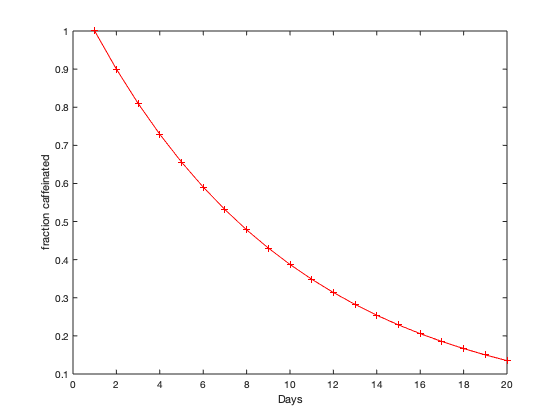

figure;
plot(x,'-+r'); 
ylabel('fraction caffeinated')
xlabel('Days')

The key data structure in Matlab is the **matrix**.

x

x =     1.0000    0.9000    0.8100    0.7290    0.6561    0.5905    0.5314    0.4783    0.4305    0.3874    0.3487    0.3138    0.2824    0.2542    0.2288    0.2059    0.1853    0.1668    0.1501    0.1351


y = [1 2 3 4 27]

y =      1     2     3     4    27


ones(1,20)

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


ones(20,1)

ans =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


zeros(1,20)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


rand(1,20)

ans =     0.4658    0.5950    0.3768    0.0709    0.7433    0.7784    0.9358    0.2583    0.6271    0.9308    0.3237    0.7367    0.8820    0.0660    0.6173    0.6915    0.9996    0.5389    0.7411    0.4156


1:10

ans =      1     2     3     4     5     6     7     8     9    10


1:2:10

ans =      1     3     5     7     9


linspace(3,7,20)

ans =     3.0000    3.2105    3.4211    3.6316    3.8421    4.0526    4.2632    4.4737    4.6842    4.8947    5.1053    5.3158    5.5263    5.7368    5.9474    6.1579    6.3684    6.5789    6.7895    7.0000


The semicolon ; is used to suppress output.

x = rand(1,10);
display('Hello world!');

Hello world!


x = rand(1,10) % no semicolon

x =     0.0624    0.6323    0.9284    0.2504    0.9216    0.3171    0.6614    0.0140    0.6006    0.6198


A key feature of Matlab is that many operations are performed on matrices. For example, the **diff() ** operator takes the difference between each neighboring element of a matrix.

diff([1 2 3 4 27])

ans =      1     1     1    23


The flow control operations like **if, if-else, for, while** are similar to other languages.

z = 0.7;
if (z < 0.5)
    display('z is small');
else
    display('z is big');
end

z is big


for i=1:10
    x(i) = i^2;
end

display(x)

x =      1     4     9    16    25    36    49    64    81   100


Operations on the elements of a matrix require a period "." . 

x = 1:10;
y = x.^2;

display(y)

y =      1     4     9    16    25    36    49    64    81   100
